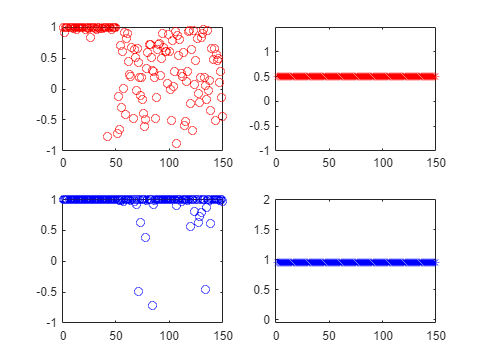

% 分类差额(margin)是真实类别的分类评分与错误类别的最大分类评分之间的差值。
% 分类差额是一个列向量，其行数与矩阵 X 中的行数相同
% 每个样本都有对应的分类差额
% 分类差额值高，高值比低值的预测更可靠。
% The classification margin is the difference between the classification score 
% for the true class and maximal classification score for the false classes.
% The classification margin is a column vector with the same number of rows 
% as in the matrix X. A high value of margin indicates a more reliable prediction than a low value.

% 优势(edge)是分类差额的加权平均值。 权重是 tree.Prior 中的类概率。
% 如果您在权重名称-值对中提供权重，
% 则这些权重将被归一化以求和到相应类别中的先验概率，然后用于计算加权平均值。
% The edge is the weighted mean value of the classification margin.
% The weights are the class probabilities in tree.Prior. 
% If you supply weights in the weights name-value pair,
% those weights are normalized to sum to the prior probabilities in the respective classes, 
% and are then used to compute the weighted average.

load fisheriris
X = meas(:,1:2);
obj1 = fitcdiscr(X,species);
M1 = margin(obj1,X,species);
E1 = edge(obj1,X,species);
figure;subplot(2,2,1)
plot(1:150,M1,'ro');hold on;
subplot(2,2,2)
plot(1:150,E1,'r*');

obj2 = fitcdiscr(meas,species);
M2 = margin(obj2,meas,species);
E2 = edge(obj2,meas,species);
subplot(2,2,3)
plot(1:150,M2,'bo')
subplot(2,2,4)
plot(1:150,E2,'b*');